% This is for 2nd JND points  
% 19 distribution candidates in total.
clear all;
close all;
clc;

Evaluation_array = zeros(1,19);
tabulate_array = [];
distribution_model_array_original = ["HalfNormal","Rayleigh","Exponential",...
    "GeneralizedExtremeValue","GeneralizedPareto","Stable","tLocationScale",...
    "BirnbaumSaunders","ExtremeValue",...
    "Gamma","Kernel",...
    "Logistic","Loglogistic","LogNormal","Nakagami",...
    "Normal","Poisson","Rician","Weibull"];
for x = 1:220
    data_test = my_sample_transform(x,2)';
    distribution_model_array = ["HalfNormal","Rayleigh","Exponential",...
    "GeneralizedExtremeValue","GeneralizedPareto","Stable","tLocationScale",...
    "BirnbaumSaunders","ExtremeValue",...
    "Gamma","Kernel",...
    "Logistic","Loglogistic","LogNormal","Nakagami",...
    "Normal","Poisson","Rician","Weibull"];
    h_array = zeros(1,length(distribution_model_array));
    p_array = zeros(1,length(distribution_model_array));
    statistic_array = zeros(1,length(distribution_model_array));
    for i = 1:length(distribution_model_array)
        distmodel = fitdist(data_test,distribution_model_array(i));
        [h_array(i), p_array(i), statistic_array(i)]= kstest(...
            data_test,'CDF',distmodel);
        
    end
    
    % This part is meant to first excluded the case whose h-value is 1.
    % Note that we can not use the p-value to judge which approximation is
    % better, but we could use the test statistic to evaluate.
    pos = find(h_array == 1);
    % Delete the element if corresponding h value is 1.
    h_array(pos) = [];
    p_array(pos) = [];
    statistic_array(pos) = [];
    distribution_model_array(pos) = [];
    % Find the model which has the smallest x^2 value.
    [min_x_square_value, pos_index] = min(statistic_array);
    % Find the original index, since maybe some of the position may be
    % excluded during judgment.
    pos_original = find(distribution_model_array_original == distribution_model_array(pos_index));
    % Count the distribution winner for this video.    
    Evaluation_array(pos_original) = Evaluation_array(pos_original) + 1;
    % Concatenate the previous tabulate_array with the distribution winner
    % for this round.
    tabulate_array = [tabulate_array,distribution_model_array_original(pos_original)];
end

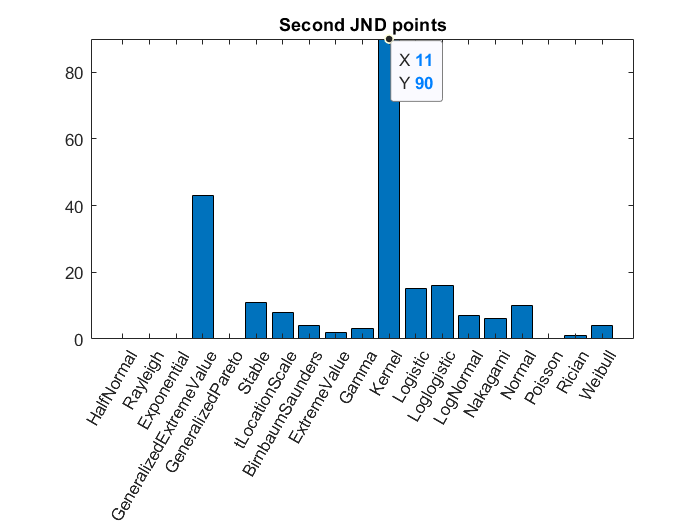

x = 1:19;
bar(x,Evaluation_array);
hold on;
title('Second JND points');
xticks(1:19);
xticklabels(["HalfNormal","Rayleigh","Exponential",...
    "GeneralizedExtremeValue","GeneralizedPareto","Stable","tLocationScale",...
    "BirnbaumSaunders","ExtremeValue",...
    "Gamma","Kernel",...
    "Logistic","Loglogistic","LogNormal","Nakagami",...
    "Normal","Poisson","Rician","Weibull"]);
xtickangle(60);

        tabulate(tabulate_array)

                    Value    Count   Percent
                 Logistic       15      6.82%
  GeneralizedExtremeValue       43     19.55%
                   Kernel       90     40.91%
                   Stable       11      5.00%
         BirnbaumSaunders        4      1.82%
           tLocationScale        8      3.64%
              Loglogistic       16      7.27%
                LogNormal        7      3.18%
                   Rician        1      0.45%
                   Normal       10      4.55%
                 Nakagami        6      2.73%
                  Weibull        4      1.82%
                    Gamma        3      1.36%
             ExtremeValue        2      0.91%
